%-------buck boost converter with PI controller
clc
t_step=0.5e-6;
s_fre=20000;%switching frequency PWM
T=1/s_fre;
% Lb=0.05;
% Cb=0.00005;
Rb=5; % Issues changing Rb
% Rb = 1e-2;
Vs=415;
Vl=400;
kp_bulk=0.4;
ki_bulk=100;

Io = 5;
delta_io = 1;%step change in current
Vc = Vl+Io*Rb

Vc = 425

D=Vc/Vs/(1+Vc/Vs)

D = 0.5060

Il=Io/(1-D)

Il = 10.1205



delta_vo = 0.5; % Output voltage ripple
% delta_iL = 0.5; % Insuctor current ripple
zeta = 1/sqrt(2);Vb = Vl;
D=Vc/Vs/(1+Vc/Vs)

D = 0.5060

Cb = (Vs-Vb)*T/2/Rb/delta_vo

Cb = 1.5000e-04

Lb =(2*Rb*D*zeta)^2*Cb

Lb = 0.0019

k=1/Vs;
kp_1=1;
ki_1=100;
kp=k*kp_1;
ki=k*ki_1;
A=zeros(3);
A(1,2)=-(1-D)/Lb-(Vs+Vc)/Lb*kp;
A(1,3)=(Vs+Vc)/Lb*ki;
A(2,1)=(1-D)/Cb;
A(2,2)=-1/(Cb*Rb)+Il/Cb*kp;
A(2,3)=-Il/Cb*ki;
A(3,2)=-1;
B(1,1)=(Vs+Vc)/Lb*kp;
B(2,1)=-Il/Cb*kp;
B(3,1)=1;

D_eig1=eig(A)

D_eig1 = 	1.0e+03 *

  -0.5442 + 1.9794i
  -0.5442 - 1.9794i
  -0.0824 + 0.0000i


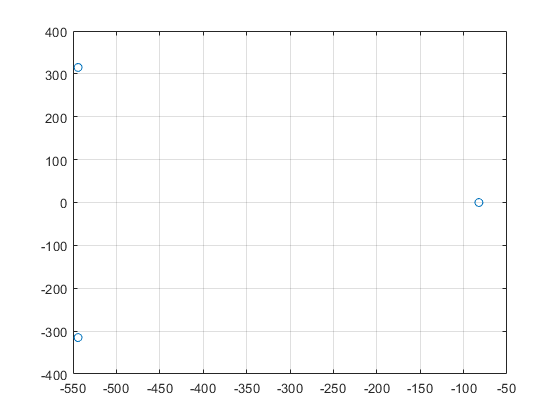

D_eig1_real=real(D_eig1);
D_eig1_ima=imag(D_eig1);

figure
scatter(D_eig1_real,D_eig1_ima/2/pi)
grid on
box on

## plot

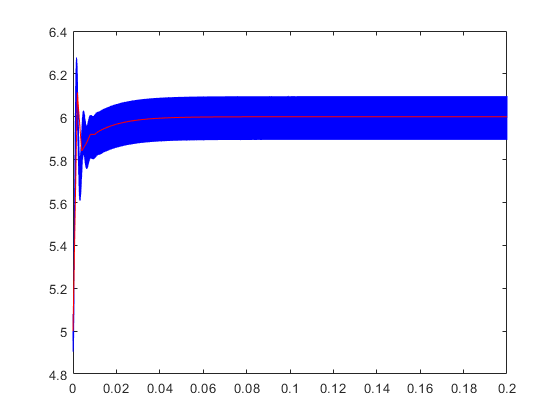


s=tf('s');
AA=eye(3)*s-A;
tf1=inv(AA)*B;
figure
plot(io.Time-0.4,io.Data,'-b')
xlim([0 0.2])
hold on
[y,tout]=step(tf1(2),0.2);

plot(tout,y*delta_io+Io,'-r')